
% Характеристики объекта
u_lim = 3;
phi_lim = 0.1;
omega_lim = 0.1;
M=-10;
J=100;

% Область построения
phi_area=pi

phi_area = 3.1416

omega_area=pi/4

omega_area = 0.7854


scaler=4

scaler = 4

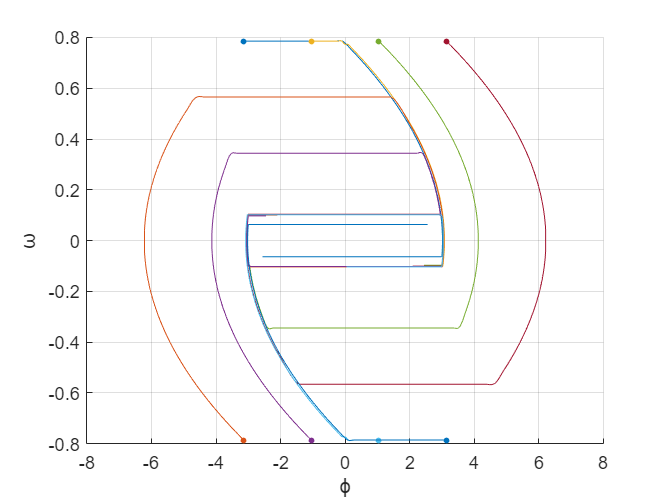


t=linspace(0,100,100e3);

P=[linspace(-phi_area,phi_area,scaler)' ones(scaler,1)*omega_area];
P=[P;linspace(-phi_area,phi_area,scaler)' -ones(scaler,1)*omega_area];

close all
figure
hold on

for i=1:4
    for j=1:scaler*2

    end
end
grid on

%plot(P(:,1),P(:,2),'--k')


for p=P'
    x0=flip(p');
    [~,y]=ode45(@(t,x) next(x,u_lim,phi_lim, omega_lim,J,M),t,x0);
    plt=plot(y(:,2),y(:,1));
    scatter(x0(2),x0(1),10,"filled","MarkerFaceColor",plt.Color)
end

xlabel("\phi")
ylabel("\omega")


if u_lim ==0
    omega = ylim;
    omega = linspace(omega(1),omega(2),100);
    phi = J*(omega.^2)/(2*M);
    phi(omega<0) = -phi(omega<0);
    p=plot(phi,omega,"k","LineWidth",3);
    legend(p,"Линия переключения","Location","best")
end

%xlim(phi_area*[-1 1])
%ylim(omega_area*[-1 1])

function y=next(x, u_lim, phi_lim, omega_lim,J,M)

% X=[omega; phi]
% Y=[dOmega/dt; dPhi/dt]



w = x(1);
phi = x(2);

% Зона нечувствительности ДУС
if abs(w) < omega_lim
    w=0;
end

% Зона нечувствительности датчика положения
if abs(phi) < phi_lim
    phi=0;
end

% Закон управления
u = phi - sign(w)* ( J * w^2 )/(2*M);
dw = (M/J)*sign(u);

% Зона нечувствительности по управлению
if abs(u) < u_lim
    dw=0;
end

y=[dw; x(1)];
end
